Name: Mukesh Aryal

Student ID: 268456

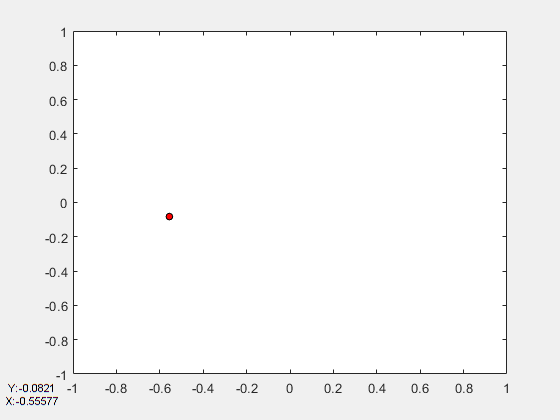

alpha=0.1;
x=0;
y=0;

fh=figure('visible','on');
h=plot(x,y,'o','MarkerFaceColor','r','MarkerSize',5,'MarkerEdgeColor','k');
axis([-1 1 -1 1]);

fh.UserData=true;
fh.WindowButtonDownFcn=@(hObject,event) set(hObject,'UserData',false);
format short;

while fh.UserData
    theta=2*pi*rand(1);
    x = x + alpha*cos(theta);
    y = y + alpha*sin(theta);
    h.XData=x;
    h.YData=y;
    hx = uicontrol('Style','text','Units','char','Position',[1 1 11 1]);
    hy= uicontrol('Style','text','Units','char','Position',[1 2 11 1]);
    hx.String = strcat('X:',num2str(x));
    hy.String = strcat('Y:',num2str(y));
    
    ax=gca;
    xx=ax.XLim;
    yy=ax.YLim;
    
    if(x<xx(1))
        ax.XLim=[xx(1)-1,xx(2)]
    elseif (x>xx(2))
            ax.XLim=[xx(1),xx(2)+1];            
    end
    
    if(y<yy(1))
        ax.YLim=[yy(1)-1,yy(2)]
    elseif (y>yy(2))
            ax.YLim=[yy(1),yy(2)+1];            
    end
    
    drawnow;
end